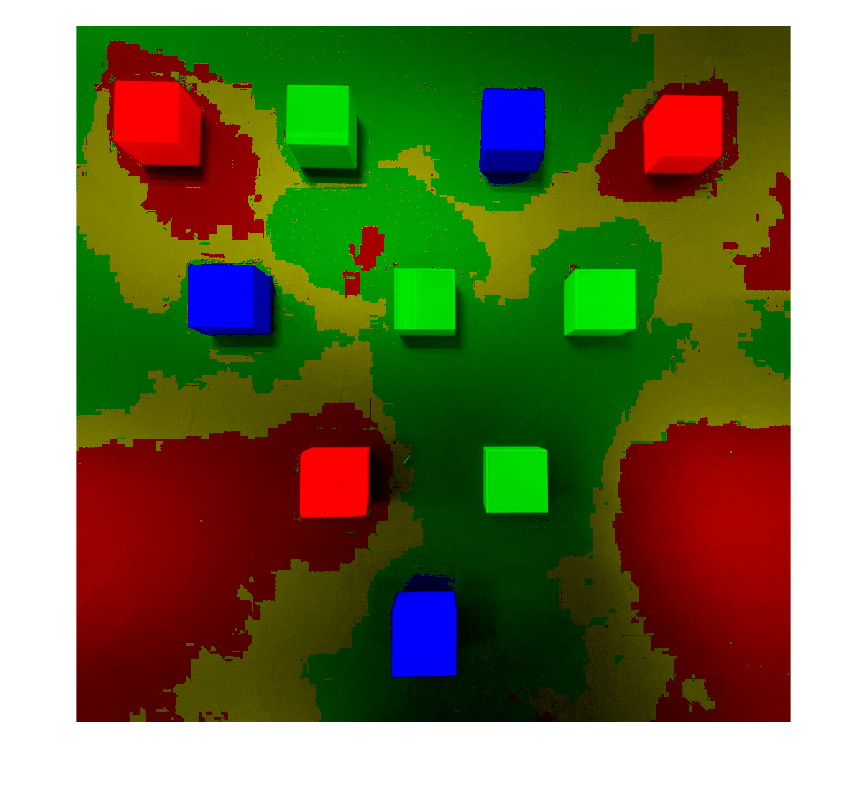

% read desired image
img = imread("setup02.png");
img = rgb2hsv(img);  %# Convert the image to HSV space
img(:,:,2) = 100;           %# Maximize the saturation
img = hsv2rgb(img);  %# Convert the image back to RGB space
imshow(img)

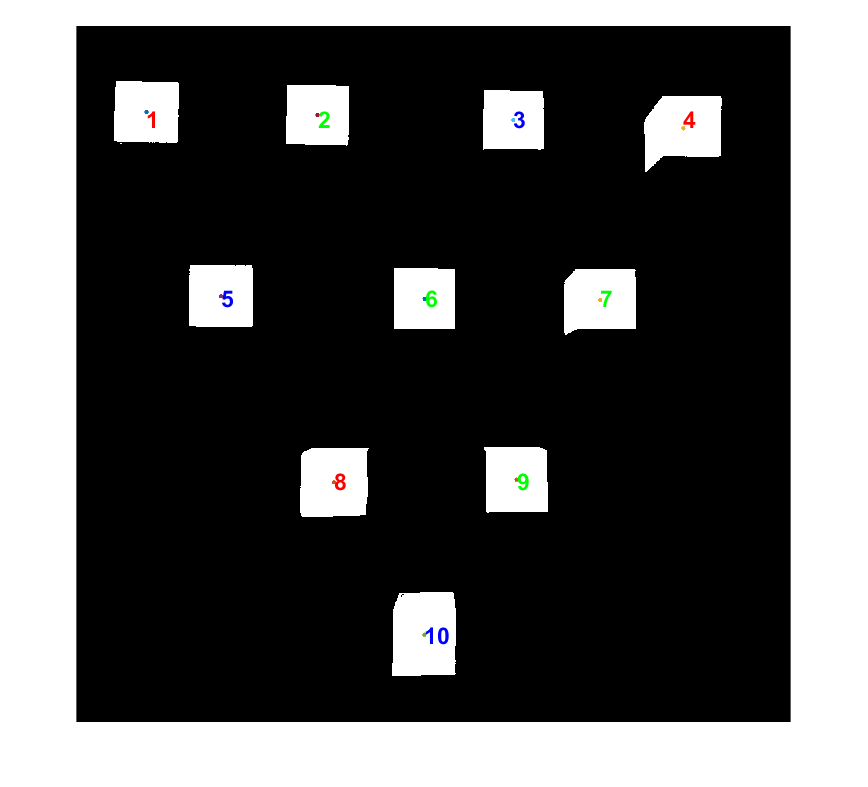


% divide image into three channels, red green and blue
red = img(:, :, 1);
green = img(:, :, 2);
blue = img(:, :, 3);

% convert into binary img   
red_b = im2bw(red, 0.9);
green_b = im2bw(green, 0.699);
blue_b = im2bw(blue, 0.9);
imshow(red_b + green_b + blue_b)

% locate areas
[v, u] = find((img > 0));

% get all centroids
centroids = [];
l = 1;

% locate centers 
% red centers
moments_r = regionprops(red_b, "Area", "Centroid");
for i=1:length(moments_r)
    if moments_r(i).Area > 2000
        plot_point(moments_r(i).Centroid', ".");
        centroids(l,1) = moments_r(i).Centroid(1);
        centroids(l,2) = moments_r(i).Centroid(2);
        l = l + 1;
    end
end

% blue centers
moments_b = regionprops(blue_b, "Area", "Centroid");
for i=1:length(moments_b)
    if moments_b(i).Area > 2000
        plot_point(moments_b(i).Centroid', ".");
        centroids(l,1) = moments_b(i).Centroid(1);
        centroids(l,2) = moments_b(i).Centroid(2);
        l = l + 1;
    end
end

% green centers
moments_g = regionprops(green_b, "Area", "Centroid");
for i=1:length(moments_g)
    if moments_g(i).Area > 2000
        plot_point(moments_g(i).Centroid', ".");
        centroids(l,1) = moments_g(i).Centroid(1);
        centroids(l,2) = moments_g(i).Centroid(2);
        l = l + 1;
    end
end

% colors
red = [moments_r.Centroid]';
green = [moments_g.Centroid]';
blue = [moments_b.Centroid]';

% store index-color
colors = [];
p = 1;
% sort centroids from minimum y to max y
x = centroids(:, 1);
y = sort(round(centroids(:, 2), 1));
% create copy of y
y_copy = y;
row = 4;
n = 1;
k = 1;
% number squares
while n == 1
    
    % go through rows
    sub_y = y_copy(1:row);

    % remove row ammount of coords
    y_copy = y_copy(row+1:length(y_copy));
    
    
    % get the xs corresponding to y values
    x_sub = [];
    for t=1:length(sub_y)
        for q=1:10
           if round(centroids(q, 2), 1) == round(sub_y(t), 1)
                x_sub(t) = round(centroids(q, 1), 1);
                break;
           end 
        end
    end

    % sort the xs
    x_sub = sort(x_sub);
    
    % get y average
    avg = sum(sub_y) / length(sub_y);

    % number squares
    for x_=x_sub
        % add colors
        for i=1:length(red)
            if round(red(i), 1) == round(x_, 1)
                text(x_, avg, num2str(p), "Color", "r", "FontSize", 14, "FontWeight", "bold");
                colors(p) = 1;
                p = p + 1;
            end
        end
        for i=1:length(green)
            if round(green(i), 1) == round(x_, 1)
                text(x_, avg, num2str(p), "Color", "g", "FontSize", 14, "FontWeight", "bold");
                colors(p) = 2;
                p = p + 1;
            end
        end
        for i=1:length(blue)
            if round(blue(i), 1) == round(x_, 1)
                text(x_, avg, num2str(p), "Color", "b", "FontSize", 14, "FontWeight", "bold");
                colors(p) = 3;
                p = p + 1;
            end
        end


    end
    % break out of loop
    if row == 1
        break;
    end

    % decrese row
    row = row - 1;

end


% answer
colors

colors =      1     2     3     1     3     2     2     1     2     3
